# Simulate Poisson point processes: First steps

## Introduction

A Poisson point process is a stochastic process in which time is continuous and events occur randomly at a certain rate.  The rate is

the expected number of events that occur per unit time.  When time is discretized, a Poisson process looks like

         [0,1,1,0,0,2,0,1,0,0,1,0]

This is interpreted as follows: 

        - No event occurred at time step 1; 

        - One event occurred at time steps 2 and 3;

        - No event occurred at time steps 4 and 5;

        - Two events occurred at time step 6; 

        - and so on.  

If each time step has size 1 second, then the time series given above states that 6 events occurred in 12 seconds. Thus, the rate of the process that produced this time series is expected to be 0.5 Hz.

## How to simulate a single process of rate 10 Hz for 1 second?

Just run what follows:

    data = simulatePoissonProcess();

data is a structure in which fields contain all the results of the simulation. For example, the time series is given by

    data.timeSeries    

ans =      1     1     2     0     0     0     0     0     0     0


The value of time in each time step is given by

    data.timeValues

ans =     0.0500    0.1500    0.2500    0.3500    0.4500    0.5500    0.6500    0.7500    0.8500    0.9500


Thus, for instance, the value of time in the 2nd time step is .15 s.  This is actually the mid-time of the 2nd time step, which begins at 0.1s and ends at 0.2s.

 The time series can be easily visualized with the matlab fonction plot.

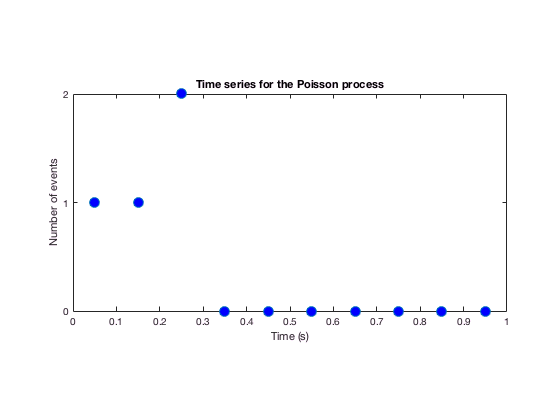

    figure()
    plot(data.timeValues, data.timeSeries,'o','MarkerSize',10,'MarkerFaceColor','b');
    title('Time series for the Poisson process');
    xlabel('Time (s)');
    ylabel('Number of events');
    yticks([0 1 2 3 4]);
    pbaspect([1 0.5 1])

The precise times at which the events occured are contain in field 'occurrenceTimes'.  For instance, the second event occured at time

data.occurrenceTimes{1}(2)

ans = 0.1943

Here, {1} refers to the first (and only one) process simulated.

## How to simulate a single Poisson process of rate 2 Hz for 10 seconds?

Set the parameters of the simulations

    rate = 2;         % The Poisson rate in Hz
    maxTime = 10;     % Time lies in the interval [0,10] (seconds)
    

and run 

    data = simulatePoissonProcess(rate, maxTime);

The data produced by the simulation now looks like this

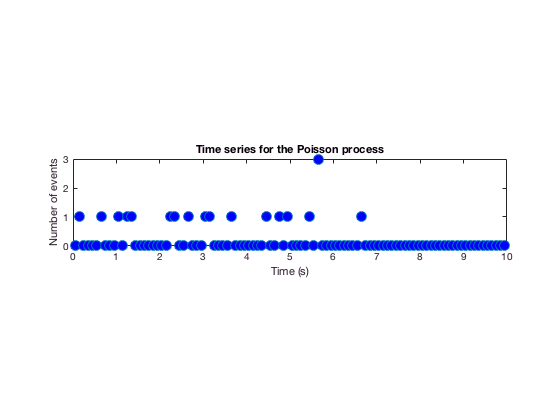

    figure()
    plot(data.timeValues, data.timeSeries,'o','MarkerSize',10,'MarkerFaceColor','b');
    title('Time series for the Poisson process');
    xlabel('Time (s)');
    ylabel('Number of events');
    yticks([0 1 2 3 4]);
    pbaspect([10 2 1])

If you wish tro change the number of time steps, you just have to modify the size of each time step.  The default value is 0.1 s.  Thus, to produce 5 times less steps, you just have to reset the time step size as

    timeStep = 0.5;         % Each time step will have a length of 0.5s

and include this parameter in the main function  as

    data = simulatePoissonProcess(rate, maxTime, timeStep);

This results in the followng time series:

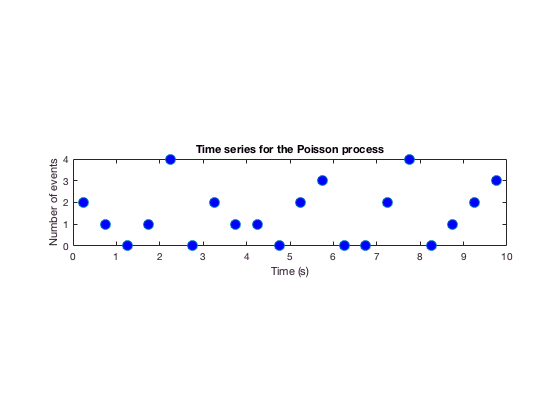

    figure()
    plot(data.timeValues, data.timeSeries,'o','MarkerSize',10,'MarkerFaceColor','b');
    title('Time series for the Poisson process');
    xlabel('Time (s)');
    ylabel('Number of events');
    yticks([0 1 2 3 4]);
    pbaspect([10 2 1])

Note that the latter time series is not related to the former one since events are produced randomly at each simulation. 

## How to simulate 3 instances of a Poisson process of rate 3 Hz for 5 seconds? 

Set

    rate = 3;        
    maxTime = 5; 
    nbProcesses = 3;  % The number of instances of the process that will be simulated   

and run (note that the time step size is not specified and will thus have its default value of 0.1s)

    data = simulatePoissonProcess(rate, maxTime, [], nbProcesses);

The field named  timeSeries is now a matrix of size 3 x 50 since there are 3 processes and 50 time steps of size 0.1 s:

    data.timeSeries

ans =      1     0     1     0     0     0     0     1     0     0     1     1     0     0     1     0     0     0     0     0     2     0     1     0     0     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     1     1     0     0     0     0     0     0     0     0     1     1     1     0     0     0     0     0     0     2     0     0     0     0     0     1     1     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     0     1     0     0     0     0     0     0     0     0     0     1     0     1     0     0     0     0     0     1     1     0     1     0     0     0     1     2     1     0


    data.timeValues

ans =     0.0500    0.1500    0.2500    0.3500    0.4500    0.5500    0.6500    0.7500    0.8500    0.9500    1.0500    1.1500    1.2500    1.3500    1.4500    1.5500    1.6500    1.7500    1.8500    1.9500    2.0500    2.1500    2.2500    2.3500    2.4500    2.5500    2.6500    2.7500    2.8500    2.9500    3.0500    3.1500    3.2500    3.3500    3.4500    3.5500    3.6500    3.7500    3.8500    3.9500    4.0500    4.1500    4.2500    4.3500    4.4500    4.5500    4.6500    4.7500    4.8500    4.9500


The time series can be visualized as before or, more effectively, by using a matrix representation.

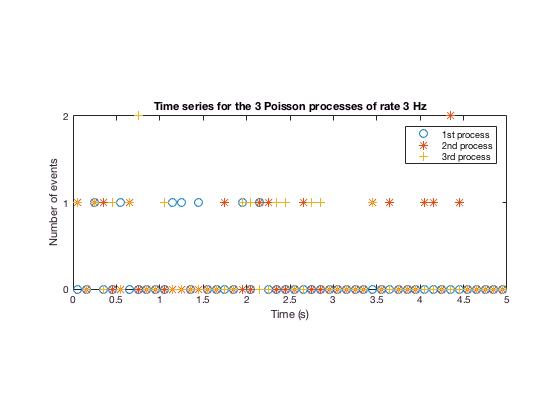

    figure()
        p1 = plot(data.timeValues, data.timeSeries(1,:),'o','MarkerSize',8);
            title('Time series for the 3 Poisson processes of rate 3 Hz');
            xlabel('Time (s)');
            ylabel('Number of events');
            yticks([0 1 2 3 4]);
            pbaspect([10 4 1])
            hold on;
        p2 = plot(data.timeValues, data.timeSeries(2,:),'*','MarkerSize',8);
            hold on;
        p3 = plot(data.timeValues, data.timeSeries(3,:),'+','MarkerSize',8);
            hold off;
            legend({'1st process', '2nd process', '3rd process'})

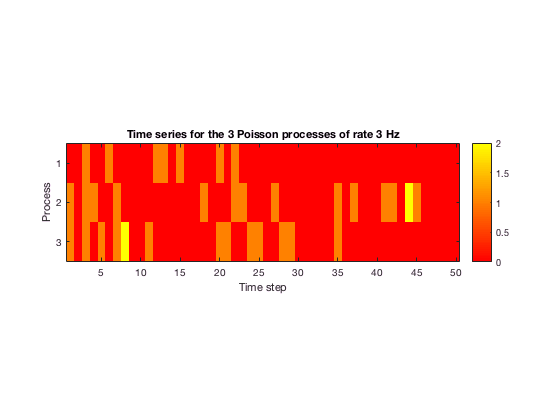

             figure()
             imagesc(data.timeSeries);
             colormap('cool');
             colorbar;
             pbaspect([10 3 1]);
             title('Time series for the 3 Poisson processes of rate 3 Hz');
             xlabel('Time step');yticks([1,2,3]);
             ylabel('Process');yticks([1,2,3]);